clear
clearAllMemoizedCaches
FFTSize = 4096;
hopSize = 2048;
wav = 'AudioTest\Bass_dth_124_bass_synth_loop_dark_Emin.wav'

wav = 'AudioTest\Bass_dth_124_bass_synth_loop_dark_Emin.wav'

Computing miraudio related to AudioTest\Bass_dth_124_bass_synth_loop_dark_Emin.wav...
Computing mirsum related to AudioTest\Bass_dth_124_bass_synth_loop_dark_Emin.wav...
Elapsed time is 0.213139 seconds.
 
audio is the Audio waveform related to AudioTest\Bass_dth_124_bass_synth_loop_dark_Emin.wav, of sampling rate 48000 Hz.


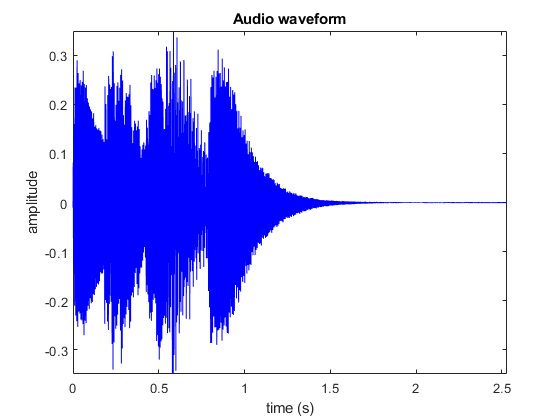

Its content is displayed in Figure 25.
 


audio = miraudio(wav)

Computing mirfilterbank related to AudioTest\Bass_dth_124_bass_synth_loop_dark_Emin.wav...
 
filterBank is the Audio waveform related to AudioTest\Bass_dth_124_bass_synth_loop_dark_Emin.wav, of sampling rate 48000 Hz.


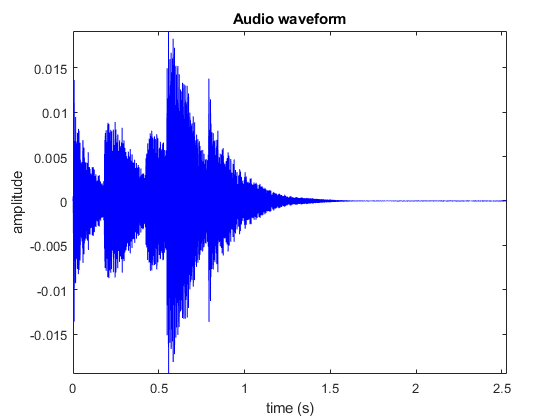

Its content is displayed in Figure 26.
 


filterBank = mirfilterbank(audio,'Gammatone','Channel',6)

frame = mirframe(filterBank,FFTSize,'sp',hopSize,'sp');


Computing mirspectrum related to AudioTest\Bass_dth_124_bass_synth_loop_dark_Emin.wav...
 
spectre is the Power Spectrum related to AudioTest\Bass_dth_124_bass_synth_loop_dark_Emin.wav, of sampling rate 48000 Hz.


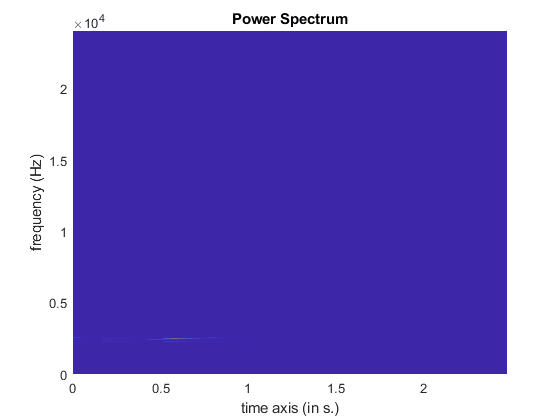

Its content is displayed in Figure 27.
 


spectre = mirspectrum(filterBank,'Frame',FFTSize,'sp',hopSize,'sp','Terhardt','Power')

Computing mirflux related to AudioTest\Bass_dth_124_bass_synth_loop_dark_Emin.wav...
 


The Spectral flux related to file AudioTest\Bass_dth_124_bass_synth_loop_dark_Emin.wav is displayed in Figure 28.


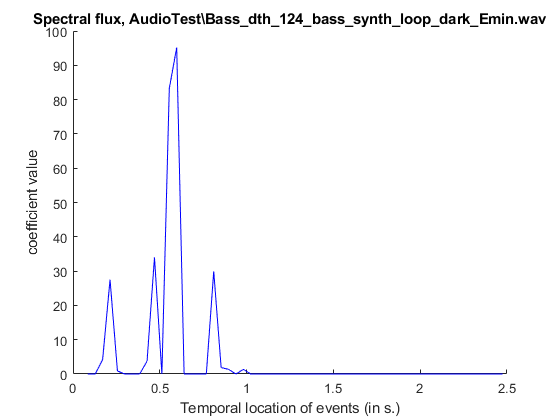


flux = mirflux(spectre,'Median','Inc','Halfwave')

fluxdata = mirgetdata(flux);
fluxdata(:,:,1)

ans =          0         0    4.2085   27.4947    0.8828         0         0         0    3.7501   34.0134         0   83.2525   95.1960         0         0         0         0   29.9312    1.8791    1.3593         0    1.3553         0         0         0         0    0.0021         0         0         0         0         0    0.0000         0         0         0         0         0         0         0    0.0000    0.0000    0.0000         0         0         0         0         0    0.0000         0


Computing mirenvelope related to AudioTest\Bass_dth_124_bass_synth_loop_dark_Emin.wav...
 
enveloppe is the Differentiated envelope (half-wave rectified) related to AudioTest\Bass_dth_124_bass_synth_loop_dark_Emin.wav, of sampling rate 3000 Hz.


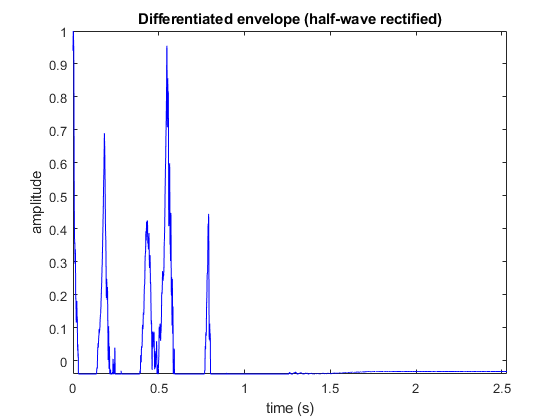

Its content is displayed in Figure 29.
 



enveloppe = mirenvelope(filterBank, 'FilterType', 'IIR','HalfwaveCenter','Diff','Normal','Center')

Computing mirpeaks related to AudioTest\Bass_dth_124_bass_synth_loop_dark_Emin.wav...
 
envelopepeaks is the Differentiated envelope (half-wave rectified) related to AudioTest\Bass_dth_124_bass_synth_loop_dark_Emin.wav, of sampling rate 3000 Hz.


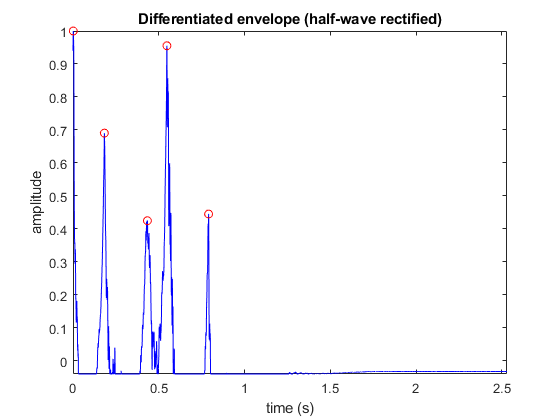

Its content is displayed in Figure 30.
 


envelopepeaks = mirpeaks(enveloppe,'Threshold',0.3,'Reso',0.05)


envelopedata =  mirgetdata(envelopepeaks);
envelopedataSort = sort(envelopedata);
envelopedataSort = sort(envelopedata(:,:,1))

envelopedataSort =     0.0018
    0.1830
    0.4339
    0.5472
    0.7905


 
segment is the Audio waveform related to AudioTest\Bass_dth_124_bass_synth_loop_dark_Emin.wav, of sampling rate 48000 Hz.


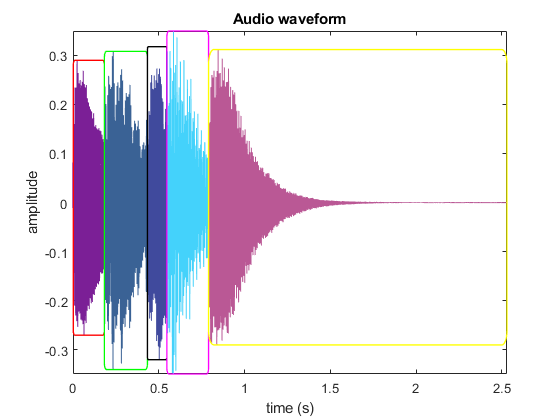

Its content is displayed in Figure 31.
 


segment = mirsegment(audio,envelopepeaks)

Computing mirfilterbank related to AudioTest\Bass_dth_124_bass_synth_loop_dark_Emin.wav...
Computing mirautocor related to AudioTest\Bass_dth_124_bass_synth_loop_dark_Emin.wav...
Computing mirsum related to AudioTest\Bass_dth_124_bass_synth_loop_dark_Emin.wav...
Computing mirautocor related to AudioTest\Bass_dth_124_bass_synth_loop_dark_Emin.wav...
Computing mirpeaks related to AudioTest\Bass_dth_124_bass_synth_loop_dark_Emin.wav...
Computing mirpeaks related to AudioTest\Bass_dth_124_bass_synth_loop_dark_Emin.wav...
Computing mirautocor related to AudioTest\Bass_dth_124_bass_synth_loop_dark_Emin.wav...
Computing mirpitch related to AudioTest\Bass_dth_124_bass_synth_loop_dark_Emin.wav...
Computing mirpeaks related to AudioTest\Bass_dth_124_bass_synth_loop_dark_Emin.wav...
 


The Pitch related to file AudioTest\Bass_dth_124_bass_synth_loop_dark_Emin.wav is displayed in Figure 32.


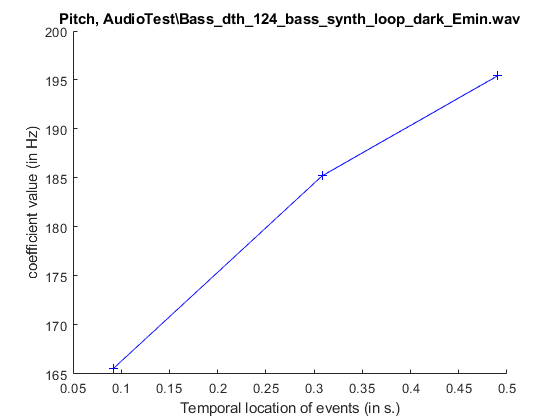

pitch = mirpitch(segment)

mirgetdata(pitch)

ans =        NaN  165.6021  185.2334  195.4475       NaN       NaN
